% 使用LSTM做分类
[XTrain1, YTrain1] = japaneseVowelsTrainData;
XTrain(1:5)

ans = 5×1 cell 数组
    {10×375 double}
    {10×375 double}
    {10×375 double}
    {10×375 double}
    {10×375 double}


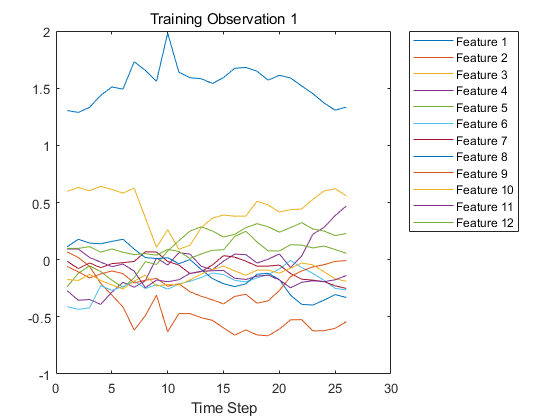

figure
plot(XTrain{2}')
xlabel("Time Step")
title("Training Observation 1")
numFeatures = size(XTrain{1},1);
legend("Feature " + string(1:numFeatures),'Location','northeastoutside')

numObservations = numel(XTrain);
for i=1:numObservations
    sequence = XTrain{i};
    sequenceLengths(i) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths);
XTrain = XTrain(idx);
YTrain = YTrain(idx);

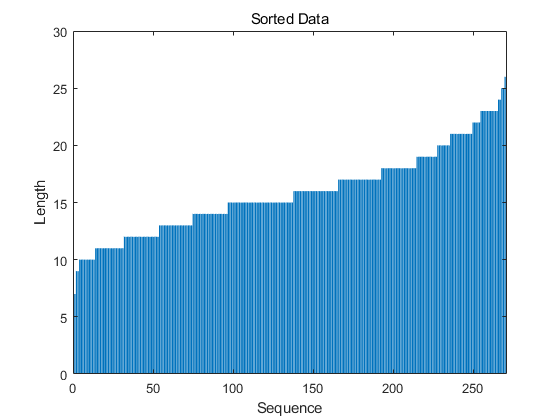

figure
bar(sequenceLengths)
ylim([0 30])
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

inputSize = 12;
numHiddenUnits = 100;
numClasses = 9;

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,'OutputMode','sequence')
    bilstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses,"BiasInitializer","narrow-normal")
    softmaxLayer
    classificationLayer]

layers =   具有以下层的 6x1 Layer 数组:

     1   ''   序列输入    序列输入: 12 个维度
     2   ''   BiLSTM    BiLSTM: 100 个隐含单元
     3   ''   BiLSTM    BiLSTM: 100 个隐含单元
     4   ''   全连接     9 全连接层
     5   ''   Softmax   softmax
     6   ''   分类输出    crossentropyex

maxEpochs = 100;
miniBatchSize = 27;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','gpu', ...
    'GradientThreshold',1, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'Verbose',0, ...
    'Plots','training-progress');

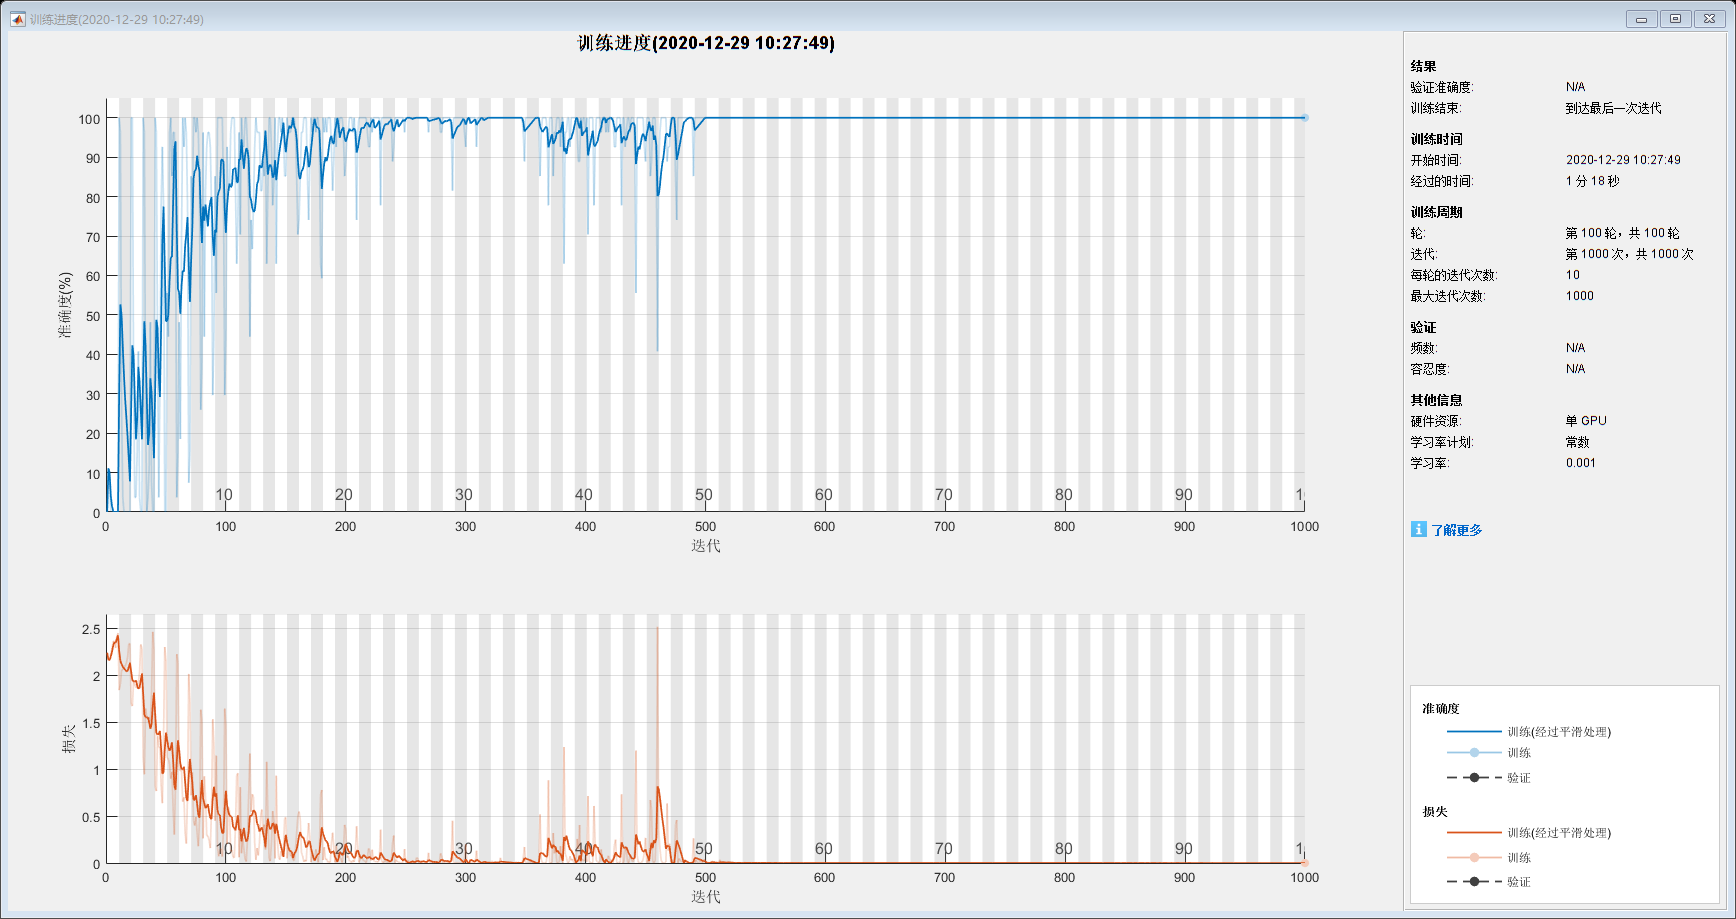

net = trainNetwork(XTrain,YTrain,layers,options);

[XTest,YTest] = japaneseVowelsTestData;
XTest(1:3)

ans = 3×1 cell 数组
    {12×19 double}
    {12×17 double}
    {12×19 double}


numObservationsTest = numel(XTest);
for i=1:numObservationsTest
    sequence = XTest{i};
    sequenceLengthsTest(i) = size(sequence,2);
end
[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTest = XTest(idx);
YTest = YTest(idx);

miniBatchSize = 27;
YPred = classify(net,XTest, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest');

acc = sum(YPred == YTest)./numel(YTest)

acc = 0.9676